# Step 1: Reaction Wheel

load('signal_3_12_5.mat');

## Load Data

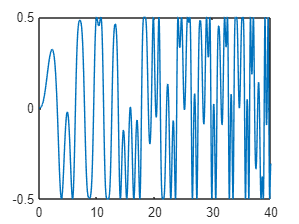

y = angular_velocity.data;
y = y(2:end);
N = size(t,2);
end_train = floor(N*1/2);
figure; 
plot(t,u)

clearvars -except y N t u

## Apply PEM

theta0 = [-5 1000 0.2]';
theta = theta0;
lambda = 0.1;
maxiter = 10000;
p = 3;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    [Abar,Bbar, C,x0] = theta2matrices_phi(theta, h);
    [yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);
    E = y - yhat;
    psi = psi_fun_phi(xhat', x0, Abar, h, u);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

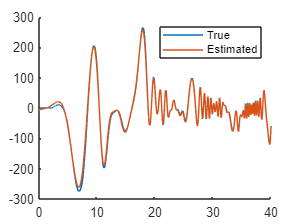

load('signal_3b_12_5.mat')
y = angular_velocity.data;
y = y(2:end);
[yhat, xhat] = simsystem(Abar, Bbar, C, x0, u);

figure;
hold on
plot(t,y);
plot(t,yhat);
legend('True', 'Estimated');


a1 = (1-Abar) / 0.01;
a5 = Bbar(1)/h;

# Part 2 : Pendulum

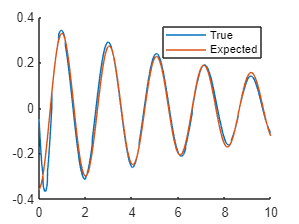

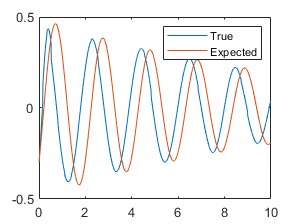

clearvars -except a1 a5
pendulum_linear_ID

# Section 3 Version 2

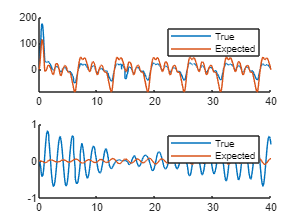

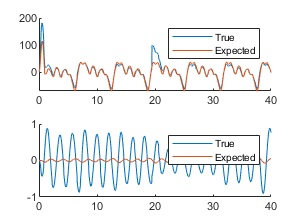

% coupled_linear_ID
ONEPARAMETERPEM